clear; clc;
close all;

%% Text Size
set(0,'DefaultAxesFontsize',6);
set(0,'DefaultTextFontsize',6);

%% Text Fonts
set(0,'DefaultTextFontname','Arial');
set(0,'DefaultAxesFontname','Arial');

figsize = [10 15 5.3 3.5];
figpos = [0.18 0.25 0.75 0.65];
lw = 0.8;

% filenames = ["esn_Nr10SR17No39" "esn_Nr20SR11No8" "esn_Nr50SR11No2" "esn_Nr500SR11No98"];
% esnsin3errorlist = zeros(4,1);
% esnlorenzerrorlist = zeros(4,1);
% for i = 1:4
%     load("esnseed\" + filenames(i) + ".mat", "edtwsin", "edtwlorenz")
%     esnsin3errorlist(i) = edtwsin;
%     esnlorenzerrorlist(i) = edtwlorenz;
% end

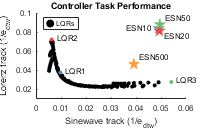

load("data\fig4_lqr_perform.mat");

colors = linspecer(4);

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',figsize);
set(gca,'Position', figpos);
set(gcf,'Visible','on');

s1 = scatter(1./sinudata(:,3), 1./lorenzdata(:,3), [], [0 0 0], 'filled', 'SizeData', 10);
hold on;
s2 = scatter(1./sinulqr123(1,3), 1./lorenzlqr123(1,3), [], colors(1,:), 'filled', 'SizeData', 10);
text(1./sinulqr123(1,3)+0.002, 1./lorenzlqr123(1,3)+0.002, "LQR1");
hold on;
s3 = scatter(1./sinulqr123(2,3), 1./lorenzlqr123(2,3), [], colors(2,:), 'filled', 'SizeData', 10);
text(1./sinulqr123(2,3)+0.002, 1./lorenzlqr123(2,3)+0.002, "LQR2");
hold on;
s4 = scatter(1./sinulqr123(3,3), 1./lorenzlqr123(3,3), [], colors(3,:), 'filled', 'SizeData', 10);
text(1./sinulqr123(3,3)+0.002, 1./lorenzlqr123(3,3)+0.002, "LQR3");
hold on;
s5 = scatter(1./esnsin3errorlist(1), 1./esnlorenzerrorlist(1), [], colors(1,:), "pentagram", 'filled', 'SizeData', 100);
text(1./esnsin3errorlist(1)-0.013, 1./esnlorenzerrorlist(1), "ESN10");
hold on;
s6 = scatter(1./esnsin3errorlist(2), 1./esnlorenzerrorlist(2), [], colors(2,:), "pentagram", 'filled', 'SizeData', 100);
text(1./esnsin3errorlist(2)+0.002, 1./esnlorenzerrorlist(2)-0.005, "ESN20");
hold on;
s7 = scatter(1./esnsin3errorlist(3), 1./esnlorenzerrorlist(3), [], colors(3,:), "pentagram", 'filled', 'SizeData', 100);
text(1./esnsin3errorlist(3)+0.002, 1./esnlorenzerrorlist(3)+0.007, "ESN50");
hold on;
s8 = scatter(1./esnsin3errorlist(4), 1./esnlorenzerrorlist(4), [], colors(4,:), "pentagram", 'filled', 'SizeData', 100);
text(1./esnsin3errorlist(4)+0.002, 1./esnlorenzerrorlist(4)+0.007, "ESN500");



leg = legend({'LQRs'});
% leg = legend([s5, s6, s7, s8], {'ESN10', 'ESN20', 'ESN50', 'ESN500'}, 'NumColumns',2);

% leg.Box = "off";
leg.ItemTokenSize = [5 1];
leg.Position = [0.28 0.8 0.05 0.05];
% leg.Location = 'north';

xlim([0 0.06]);
ylim([0.01 0.1]);

xlabel('Sinewave track (1/e_{dtw})');
ylabel('Lorenz track (1/e_{dtw})');
title("Controller Task Performance");